clc; clear; % Clear data & Memory
train = xlsread('C:\Users\Kevin Huang\Desktop\Financial-Product\Final Project\train.xls');
test = xlsread('C:\Users\Kevin Huang\Desktop\Financial-Product\Final Project\test.xls')

test =   101.2100
  102.1600
  101.1700
  101.8300
  101.6900
  102.1100
  102.4700
  102.4000
  102.5700
  102.6400



for i=2:length(train)
    train_infl(i-1,1)= train(i,1)/train(i-1,1);
end


for i=2:length(test)
    test_infl(i-1,1)= test(i,1)/test(i-1,1);
end

test_infl = [train_infl(end,1);test_infl];

Mdl = arima(4,1,4)

Mdl =   arima with properties:

     Description: "ARIMA(4,1,4) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 5
               D: 1
               Q: 4
        Constant: NaN
              AR: {NaN NaN NaN NaN} at lags [1 2 3 4]
             SAR: {}
              MA: {NaN NaN NaN NaN} at lags [1 2 3 4]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: NaN

EstMdl = estimate(Mdl,train);

 
    ARIMA(4,1,4) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.13043      0.042774         3.0494       0.0022928
    AR{1}       -0.31351       0.09949        -3.1512        0.001626
    AR{2}       -0.31557      0.096447         -3.272        0.001068
    AR{3}        -0.3114      0.093593        -3.3271       0.0008774
    AR{4}        0.68263      0.097882          6.974      3.0801e-12
    MA{1}        0.15992      0.082678         1.9343         0.05308
    MA{2}        0.16012      0.077484         2.0665        0.038781
    MA{3}        0.16036      0.077061       


res = infer(EstMdl,train);
prediction = train+res;
[yF,yMSE] = forecast(EstMdl,12,'Y0',train);


for i=2:length(yF)
    infl_pred(i-1,1)=yF(i,1)/yF(i-1,1);
end

infl_pred = [yF(1,1)/train(end);infl_pred];

cut = 48;
num_t = transpose(1:1:cut);
pred = [prediction;yF];
true = [train;test(1:12,1)];
xlabel('Time period')
ylabel('CPI Level')
plot(num_t,pred(end-cut+1:end))
hold on 
plot(num_t,true(end-cut+1:end))
hold on 
xline(37,'--r')

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 37
            Color: [1 0 0]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


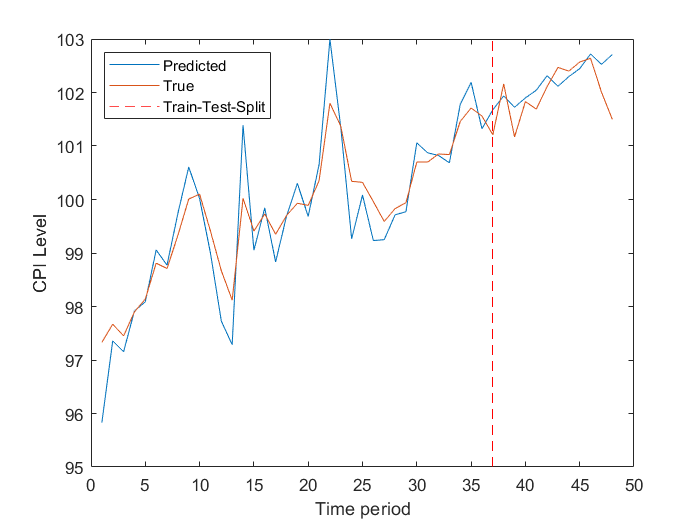

legend('Predicted','True','Train-Test-Split','Location','northwest')